# B777-200LR Walkthrough — constraint diagram, sizing, and T–S

This live script sizes the Boeing 777-200LR from end to end. It builds the Level-2 discipline models, draws the constraint diagram, sizes the aircraft with the Level-2 sizing loop, and then draws the T–S diagram that places that aircraft inside the whole design space.

The 777 is the framework's large jet-transport example. Its provenance is the Martins design metabook: the constraint and T–S method is Example 4.2 (Chapter 4), and the Level-2 component build-up weights are Chapter 7. The real aircraft has a maximum takeoff weight near 766,800 lbf, which is the ground truth for this example.

Method reference: metabook Chapter 4 (Example 4.2, §4.11 constraint analysis, §4.12 T–S diagram, Figs. 4.6 and 4.7) and Chapter 7 (component build-up weights, Algorithm 5). The sizing loop follows the preliminary-design framework (Martins slide 8): a two-state fixed point on takeoff weight and thrust.

This walkthrough does the following steps:

- it builds the B777 Level-2 discipline stack

- it draws the constraint diagram and marks the actual 777

- it sizes the aircraft with the Level-2 loop and reports the three sized values

- it draws the T–S diagram and reads the feasible region

## Make the sizing framework visible

This block adds the framework to the MATLAB path. If you already ran `tests/run_all_tests`, the path is set and this block does nothing.

if isempty(which("b777_spec_path"))
    try
        here = fileparts(matlab.desktop.editor.getActiveFilename);
    catch
        here = pwd;
    end
    root = here;
    while ~isfolder(fullfile(root, "src")) || ~isfolder(fullfile(root, "examples", "B777"))
        parent = fileparts(root);
        if strcmp(parent, root)
            error("Could not find the sizing/ root. Add its src/ and examples/ folders to the path, or run this file from inside air_vehicle_design/sizing.");
        end
        root = parent;
    end
    addpath(genpath(fullfile(root, "src")));
    addpath(genpath(fullfile(root, "examples")));
end

## Build the B777 Level-2 discipline stack

Each analysis needs a set of discipline objects. The caller builds them and injects them, so the wiring is explicit. The order matters, because later objects read earlier ones: geometry first, then the aerodynamics object injects geometry so its drag tracks the wing area, and the weights object injects both geometry and propulsion so the empty weight tracks the wing area and the engine thrust.

sp   = b777_spec_path(1);
rp   = b777_requirements_path();
geom = B777GeomL2(sp);
prop = B777PropL1(sp);
aero = B777AeroL1(geom, sp);
tail = B777TailL1(geom);
wts  = B777WeightsL2(sp, geom, prop);
miss = MissionAnalysisL1.from_requirements(aero, prop, geom, rp, "long_range");
stack = table( ...
    ["geom"; "prop"; "aero"; "tail"; "wts"; "miss"], ...
    [string(class(geom)); string(class(prop)); string(class(aero)); ...
     string(class(tail)); string(class(wts)); string(class(miss))], ...
    ["trapezoidal planform, exposed + wetted areas (Ch. 7)"; ...
     "2x GE90, density-ratio lapse + cruise TSFC"; ...
     "drag polar CD0 = Cfe*S_wet/S_ref (tracks the wing)"; ...
     "tail volume-coefficient sizing"; ...
     "component build-up OEW(W_TO) (Ch. 7)"; ...
     "long-range mission fuel"], ...
    'VariableNames', ["Object", "Class", "Role"])

stack = 6×3 table
    Object           Class                                    Role                         
    ______    ___________________    ______________________________________________________

    "geom"    "B777GeomL2"           "trapezoidal planform, exposed + wetted areas (Ch. 7)"
    "prop"    "B777PropL1"           "2x GE90, density-ratio lapse + cruise TSFC"          
    "aero"    "B777AeroL1"           "drag polar CD0 = Cfe*S_wet/S_ref (tracks the wing)"  
    "tail"    "B777TailL1"           "tail volume-coefficient sizing"                      
    "wts"     "B777WeightsL2"        "component build-up OEW(W_TO) (Ch. 7)"                
    "miss"    "MissionAnalysisL1"    "long-range mission fuel"                             


## The constraint diagram

The constraint analysis reads the ten 777 conditions from the requirements file: two field-length limits, six FAR-25 climb gradients, a ceiling, and cruise. Each condition draws one curve in the thrust-to-weight versus wing-loading plane. A feasible design sits above every producer curve and to the left of every wall.

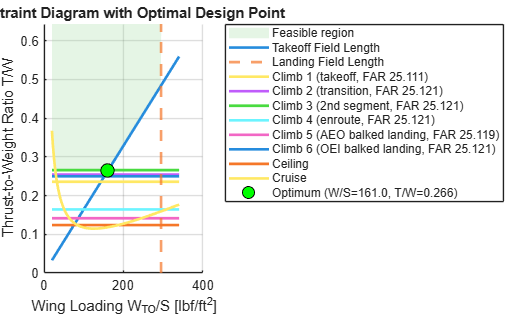

WS_sweep = linspace(20, 340, 321);   % psf
ca = ConstraintAnalysis.from_requirements(aero, prop, rp, ...
    B777ConstraintSet.constraint_map(), WS_sweep);
fig = ca.plot_diagram();
fig.Color = 'w';
if isprop(fig, 'Theme'), fig.Theme = 'light'; end

For a jet transport, down and to the right is the better direction: a low thrust-to-weight is a small engine, and a high wing loading is a small, efficient wing. So the design point is the down-right corner of the feasible region, where the second-segment-climb floor meets the takeoff-field-length line. The real 777 sits just up and to the left of that corner, inside the feasible region, because it carries margin.

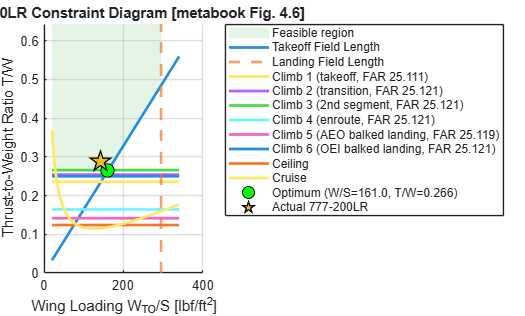

WS_actual = 142.45;                  % psf  [metabook Table 4.3]
TW_actual = 220000 / 766800;         % = 0.287  [metabook Fig. 4.7 caption]
ax = fig.CurrentAxes;
hold(ax, 'on');
plot(ax, WS_actual, TW_actual, 'kp', 'MarkerSize', 16, 'LineWidth', 1.0, ...
    'MarkerFaceColor', [0.95 0.75 0.10], 'DisplayName', 'Actual 777-200LR');
title(ax, 'B777-200LR Constraint Diagram [metabook Fig. 4.6]');
hold(ax, 'off');

[WS_opt, TW_opt] = ca.optimal_point();
constraintPoint = table([WS_opt; WS_actual], [TW_opt; TW_actual], ...
    'VariableNames', ["WS_psf", "TW"], 'RowNames', ...
    {'Design point (down-right corner)', 'Actual 777-200LR'})

constraintPoint = 2×2 table
                                        WS_psf      TW   
                                        ______    _______

    Design point (down-right corner)       161    0.26573
    Actual 777-200LR                    142.45    0.28691


## Size the aircraft with the Level-2 loop

The Level-2 sizing loop solves for the whole aircraft at once. It is a two-state fixed point on the takeoff gross weight and the sea-level thrust (Martins slide 8). Every iteration does five things: it re-solves the design point $ (W/S, T/W) $ from the constraint diagram, it resizes the wing to $ S_{ref} = W_{TO} / (W/S) $, it resizes the tail, it writes the new thrust $ T_{SL} = (T/W) \cdot W_{TO} $, and it closes the takeoff weight from the mission fuel and the empty weight. So the loop produces all three sizing outputs together: the takeoff weight, the thrust, and the wing area.

The guesses of 700,000 lbf and 200,000 lbf are set off the answer on purpose, so a converged result shows the loop finds the values rather than starting at them.

loop = SizingLoopL2(aero, prop, wts, geom, miss, ca, tail);
result = loop.run(700000, 200000);
sized = table( ...
    [result.W_TO; result.T_SL; result.S_ref], ...
    'VariableNames', "Value", 'RowNames', ...
    {'W_TO  takeoff gross weight [lbf]', 'T_SL  sea-level thrust [lbf]', ...
     'S_ref  wing area [ft^2]'})

sized = 3×1 table
                                          Value   
                                        __________

    W_TO  takeoff gross weight [lbf]    7.4006e+05
    T_SL  sea-level thrust [lbf]        1.9667e+05
    S_ref  wing area [ft^2]                 4598.5


The loop also reports the design point it converged to and the weight breakdown behind the closure. The wing loading and thrust-to-weight are the constraint-diagram optimum the loop settled on.

p     = aero.drag_polar([]);
LDmax = 1 / (2 * sqrt(p.CD0 * p.K1));
tsfc  = prop.get_TSFC(AircraftState(40000, 0.85));
detail = table( ...
    [result.WS; result.TW; result.W_OEW; result.W_fuel; result.S_ht; result.S_vt; ...
     LDmax; tsfc; result.n_iter], ...
    'VariableNames', "Value", 'RowNames', ...
    {'W/S  wing loading [psf]', 'T/W  thrust-to-weight', ...
     'W_OEW  empty weight [lbf]', 'W_fuel  mission fuel [lbf]', ...
     'S_ht  horizontal tail [ft^2]', 'S_vt  vertical tail [ft^2]', ...
     'L/D_max  (clean polar)', 'cruise TSFC [1/hr]', 'iterations'})

detail = 9×1 table
                                      Value   
                                    __________

    W/S  wing loading [psf]             160.93
    T/W  thrust-to-weight              0.26575
    W_OEW  empty weight [lbf]       3.2268e+05
    W_fuel  mission fuel [lbf]      3.3856e+05
    S_ht  horizontal tail [ft^2]        907.84
    S_vt  vertical tail [ft^2]          800.71
    L/D_max  (clean polar)              20.229
    cruise TSFC [1/hr]                    0.52
    iterations                              52


The table below compares the three sized values with the real 777. The wing area lands almost exactly on the real wing. The takeoff weight sits a few percent low, and the thrust lower still, because the loop sizes the constraint envelope optimum: the smallest engine that still meets every requirement. The real 777 carries thrust margin above that corner (its thrust-to-weight is 0.287 versus the loop's 0.266), so its engine and takeoff weight are larger.

target = [766800; 220000; 4605];
got    = [result.W_TO; result.T_SL; result.S_ref];
sizedVsReal = table(got, target, 100*(got - target)./target, ...
    'VariableNames', ["Sized", "Real", "Percent_diff"], 'RowNames', ...
    {'W_TO [lbf]', 'T_SL [lbf]', 'S_ref [ft^2]'})

sizedVsReal = 3×3 table
                      Sized         Real       Percent_diff
                    __________    _________    ____________

    W_TO [lbf]      7.4006e+05    7.668e+05       -3.4872  
    T_SL [lbf]      1.9667e+05      2.2e+05       -10.603  
    S_ref [ft^2]        4598.5         4605      -0.14084  


## The T–S diagram

The sizing loop found one aircraft. The T–S diagram shows the whole design space. It sweeps the wing area and the sea-level thrust, and at every cell it sizes a complete aircraft with a converged weight. It draws each constraint as a curve in the same plane, shades the region where a sized aircraft meets every requirement, and overlays fuel-burn contours. The transport empty weight scales with the takeoff weight, so the fuel contours here are genuinely curved.

The grid below is coarser than the study script `run_b777_TS_diagram.m` uses, so the live script stays responsive. Each cell is still a full sizing solve, so the scan takes a moment.

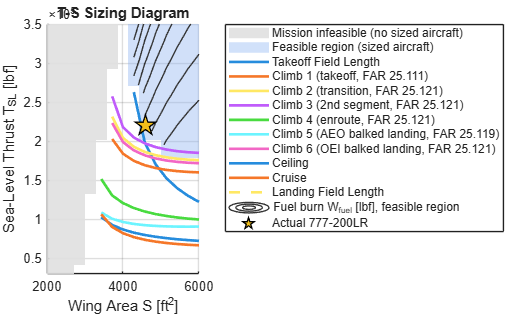

ts = TSDiagram(aero, prop, wts, geom, miss, ca, tail);
S_grid = linspace(2000, 6000, 15);      % ft^2
T_grid = linspace(30000, 350000, 15);   % lbf
actual = struct('T', 220000, 'S', 4605, 'label', "Actual 777-200LR");
ts.plot('S_grid', S_grid, 'T_grid', T_grid, 'actual', actual);

Read the diagram like this. The blue region is the set of aircraft that fly the long-range mission and meet every requirement. Each solid line is one constraint, and each dashed line is a wing-area wall. The fuel-burn contours show the objective: within the feasible region, the design that burns the least fuel is the best. The star marks the actual 777, which sits inside the feasible region.

## Summary

The Level-2 discipline models placed the ten constraints on the thrust-to-weight versus wing-loading plane, and the down-right corner gave the transport design point. The Level-2 sizing loop then solved for all three outputs together — takeoff weight, thrust, and wing area — by re-solving that design point every iteration while the weight closed. It sized the constraint envelope optimum, a smaller-engine aircraft than the real, margin-carrying 777, so its thrust and takeoff weight came out a few percent low while the wing area matched. The T–S diagram then placed that aircraft inside the feasible region, with the fuel contours pointing to the best design.

To reproduce these results as stand-alone studies, run `studies/run_b777_constraint_diagram.m`, `studies/run_b777_TS_diagram.m`, and `sanity_checks/b777_metabook_comparison.m`.